# A notebook to calcuate Figure 3B & D, Tables 4 and 5

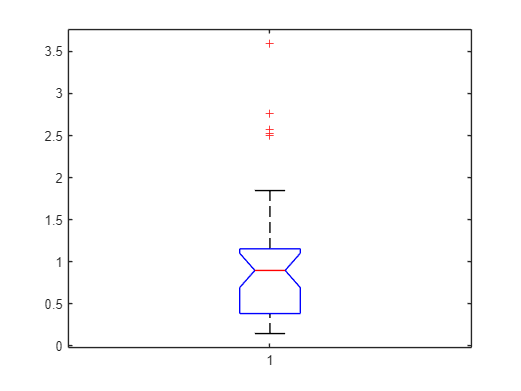

clear;
close all;
load("datasets_with_spike_waveforms_2000Hz.mat")

idx_b1_datasets = find(contains([datasets.sess{:,1}],'b1'))';
spatial_infos = zeros(length(idx_b1_datasets),1);
avg_rate = zeros(length(idx_b1_datasets),1);
performance = zeros(length(idx_b1_datasets),1);
mean_bird_flights = zeros(length(idx_b1_datasets),1);
num_birds = zeros(length(idx_b1_datasets),1);
cm2px = 3.6757*ones(length(idx_b1_datasets),1);
animal = zeros(size(cm2px));

% loop over each behavioral session
for h = 1:length(idx_b1_datasets)
    wh = idx_b1_datasets(h);
    BIRD_idxs = datasets.BIRDs{wh,1}.chain_idx(datasets.BIRDs{wh,1}.chain_dur>0);
    BIRD_init = zeros(size(BIRD_idxs));
    BIRD_last = zeros(size(BIRD_idxs));
    BIRD_flight = zeros(size(BIRD_idxs));
    BIRD_displacement = zeros(size(BIRD_idxs));

    % performance calculation
    total_num_trials = length(datasets.parsed_path{wh,1}.TrialIndices)-1;
    correct_trials = sum(strcmp(datasets.parsed_path{wh,1}.Evaluate(2:total_num_trials+1,2),"Correct")==1);
    performance(h) = correct_trials/total_num_trials;

    if datasets.animal(wh) == 149
        cm2px(h) = 14;
    end
    animal(h) = datasets.animal(wh);
    
    for i = 1:length(BIRD_init)
        BIRD_init(i) = BIRD_idxs{i}(1);
        BIRD_stop =  BIRD_idxs{i}(end);
        BIRD_last(i) = BIRD_idxs{i}(end);
        BIRD_flight_temp = 0;
        for j = 1:length(BIRD_idxs{i})-1
            BIRD_flight_temp = BIRD_flight_temp + norm([datasets.data{wh,2}(BIRD_idxs{i}(j+1)),datasets.data{wh,3}(BIRD_idxs{i}(j+1))]-...
                [datasets.data{wh,2}(BIRD_idxs{i}(j)),datasets.data{wh,3}(BIRD_idxs{i}(j))]);
        end
        BIRD_flight(i) = BIRD_flight_temp;
        BIRD_displacement(i) = norm([datasets.data{wh,2}(BIRD_stop),datasets.data{wh,3}(BIRD_stop)]-...
            [datasets.data{wh,2}(BIRD_init(i)),datasets.data{wh,3}(BIRD_init(i))]);
    end
    mean_bird_flights(h) = nanmean(BIRD_flight/cm2px(h));
    num_birds(h) = length(BIRD_init);

    % formula form Skaggs et al NEURIPS
    N_bins = 15; % N = 15 is what the text says
    %spatial info, first total spikes
    [N_x,Xedge,YEdge]=histcounts2(datasets.pos{wh}.x,datasets.pos{wh}.y,N_bins);
    [N_sp,~,~] = histcounts2(datasets.data{wh,2},datasets.data{wh,3},Xedge,YEdge);
    [pdf_pos,~,~] = histcounts2(datasets.pos{wh}.x,datasets.pos{wh}.y,Xedge,YEdge,"Normalization","probability");
    lambda_x = (N_sp./(N_x+1e-8));
    lambda = sum(lambda_x.*pdf_pos,"all"); % p(x)dx = Prob(x) 
    I_total_sp = sum(lambda_x.*log2((lambda_x+1e-8)/lambda).*pdf_pos,"all")/lambda;

    avg_rate(h) = lambda;

    spatial_infos(h) = I_total_sp;
end

figure(1)
boxplot(spatial_infos,"Notch","on")


sp_vs_flight = table();
sp_vs_flight.spatial_info = spatial_infos;
sp_vs_flight.mean_flight = mean_bird_flights;
sp_vs_flight.animal = animal;
sp_vs_flight.performance = performance;

sp_vs_flight_model = fitglme(sp_vs_flight,'spatial_info ~ 1 + mean_flight  + (1|animal)','CovariancePattern','Diagonal','Link','reciprocal','Distribution','Gamma')

sp_vs_flight_model = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              35
    Fixed effects coefficients           2
    Random effects coefficients          7
    Covariance parameters                2
    Distribution                    Gamma 
    Link                            Reciprocal
    FitMethod                       MPL   

Formula:
    spatial_info ~ 1 + mean_flight + (1 | animal)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    61.326    67.547    -26.663          53.326  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF    pValue       Lower        Upper   
    {'(Intercept)'}          1.3672     0.39245    3.4837    33    0.0014172      0.56872      2.1656
    {'mean_flight'}        0.010759    0.004397    2.4469    33       0.0199    0.0018134    0

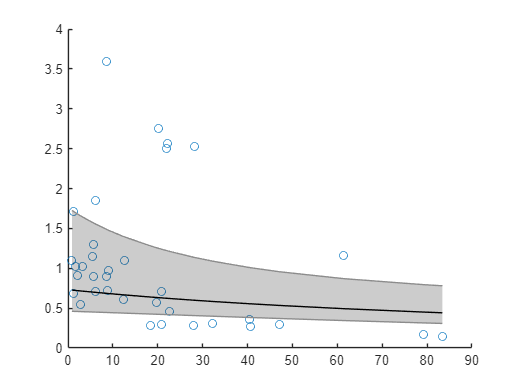


% unconditional (marginalized) CI
[pred_mean,pred_CI]=predict(sp_vs_flight_model,'Conditional',false);

[sort_mean_bird_flights,sort_i]=sort(mean_bird_flights);

% Figure 3D, Table 5
figure()
scatter(mean_bird_flights,spatial_infos(:,1))
hold on
shadedErrorBar(sort_mean_bird_flights,pred_mean(sort_i,:),[pred_CI(sort_i,2)-pred_mean(sort_i,:),pred_mean(sort_i,:)-pred_CI(sort_i,1)])
hold off


% Figure 3B, table 4
sp_vs_flight_model_glm = fitglm(sp_vs_flight,'performance ~ 1 + spatial_info','Distribution','normal')

sp_vs_flight_model_glm = Generalized linear regression model:
    performance ~ 1 + spatial_info
    Distribution = Normal

Estimated Coefficients:
                    Estimate       SE       tStat       pValue  
                    ________    ________    ______    __________

    (Intercept)      0.51121    0.050958    10.032    1.4944e-11
    spatial_info    0.078014    0.038213    2.0415      0.049258


35 observations, 33 error degrees of freedom
Estimated Dispersion: 0.0354
F-statistic vs. constant model: 4.17, p-value = 0.0493

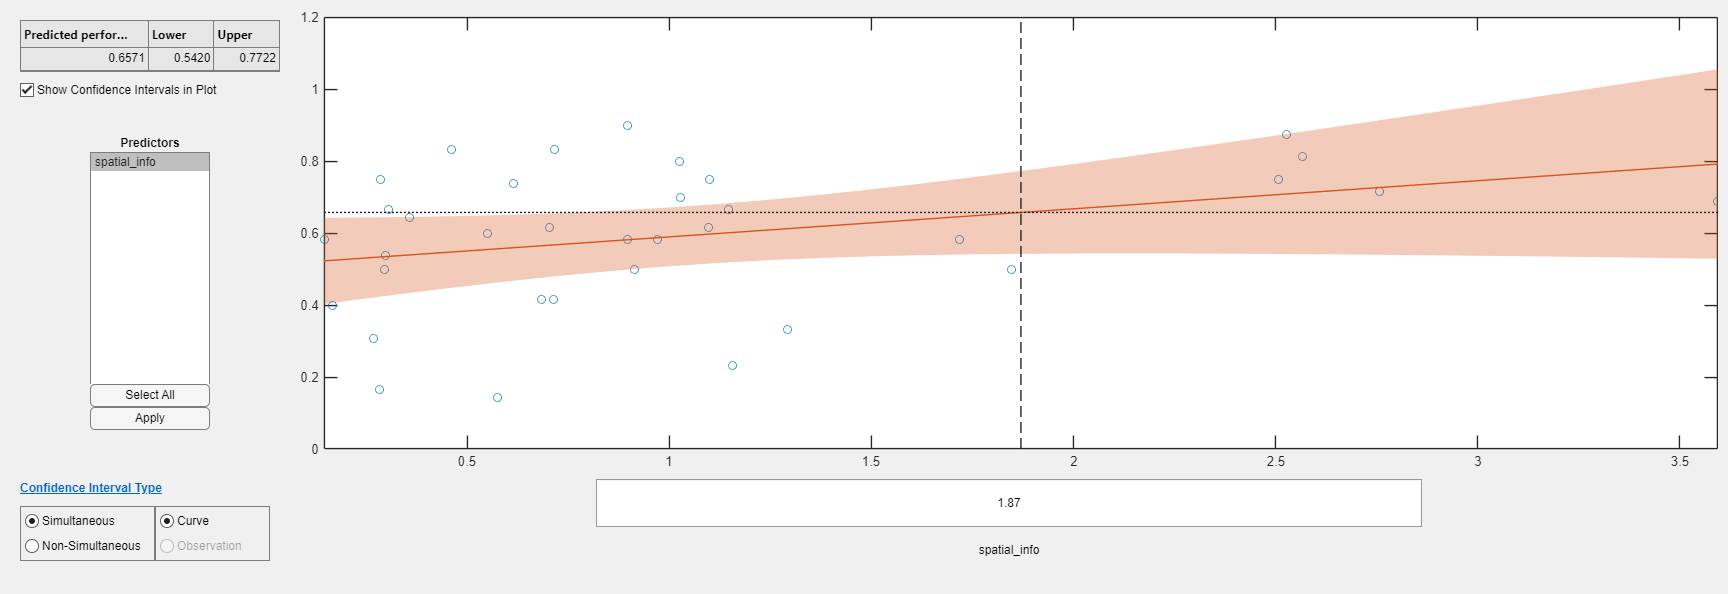

plotSlice(sp_vs_flight_model_glm)